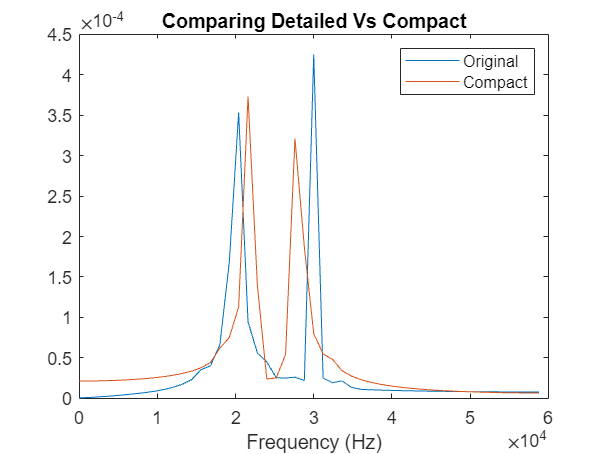

clear all
close all
clc

handel = load("handel.mat");
laughter = load("laughter.mat");
origsample = handel.Fs;
handel.y = handel.y(linspace(1,handel.Fs*5,handel.Fs*5));
laughter.y = laughter.y(linspace(1,laughter.Fs*5,laughter.Fs*5));
fc = 2000; % Hz Cutoff Frequency
[num, den] = butter(5,2*pi*fc,"low",'s'); % Generating butter filter coefficients
H_butter2k = tf(num,den); % generating our transfer function
fc = 1000; % Hz Cutoff Frequency
[num, den] = butter(5,2*pi*fc,"low",'s'); % Generating butter filter coefficients
H_butter1k = tf(num,den); % generating our transfer function
timevec = linspace(0,5,40960); % creating a 5 second time vector
handel2k = lsim(H_butter2k,transpose(handel.y),timevec); % Filtering our handel audio sample
laughter2k = lsim(H_butter2k,transpose(laughter.y),timevec); % Filtering our laughter audio sample
handel1k = lsim(H_butter1k,transpose(handel.y),timevec); % Filtering our handel audio sample
laughter1k = lsim(H_butter1k,transpose(laughter.y),timevec); % Filtering our laughter audio sample
samp_rate = 120000; % Finding our sample rate
target_samples = samp_rate*5; % Setting a total number of sampples
handel2k = resample((1.+(handel2k./(max(abs(handel2k))))),target_samples,length(handel2k)); % resample handel to 600000 samples
laughter2k = resample((1.+(laughter2k./(max(abs(laughter2k))))),target_samples,length(laughter2k)); % resample laughter to 600000 samples
handel1k = resample((1.+(handel1k./(max(abs(handel1k))))),target_samples,length(handel1k)); % resample handel to 600000 samples
laughter1k = resample((1.+(laughter1k./(max(abs(laughter1k))))),target_samples,length(laughter1k)); % resample laughter to 600000 samples
tlength = linspace(0,5,target_samples); % Setting a 5 second time vector for generating carrier signals
ThirtyKHz= transpose(cos(30000*2*pi*tlength));% 30 KHz
TwentyKHz = transpose(cos(20000*2*pi*tlength));% 20 KHz
TwentyTwoKHz = transpose(cos(22000*2*pi*tlength));% 30 KHz
TwentyEightKHz = transpose(cos(28000*2*pi*tlength));% 30 KHz
handelthirty = handel2k.*ThirtyKHz; % Modulating the handel sample with the thirty khz
laughtertwenty = laughter2k.*TwentyKHz; % Modulating the laughter sample with the twenty khz
SignalSum = handelthirty+laughtertwenty;
handel28 = handel1k.*TwentyEightKHz; % Modulating the handel sample with the thirty khz
laughter22 = laughter1k.*TwentyTwoKHz; % Modulating the laughter sample with the twenty khz
SignalSum2 = handel28+laughter22;
myFFT(SignalSum,120000,100)
hold on
myFFT(SignalSum2,120000,100)
hold on
title("Comparing Detailed Vs Compact")
legend("Original","Compact")